clc
clear all
close all

%loading data
load('Received.mat')

%all_x_coor = -1200:1:-800;
all_x_coor = -1200:2:1200;
all_y_coor = 1:2:350;
%all_y_coor = 150;
energy_values = zeros(size(all_y_coor,2), size(all_x_coor,2));
i=0;
for x = all_x_coor
    i=i+1;
    j=0;
     x
    for y=all_y_coor
        j=j+1;
        sig = get_signal_at_a_point(RecSig,x, y);
        energy_sig = sig.^2;
        energy_val = sum(sum(energy_sig));
        %energy_val = max(max(sig))
        energy_values(j,i) = energy_val;
        
        
    end
    %pause(0.3)
end

x = -1250

x = -1248

x = -1246

x = -1244

x = -1242

x = -1240

x = -1238

x = -1236

x = -1234

x = -1232

x = -1230

x = -1228

x = -1226

x = -1224

x = -1222

x = -1220

x = -1218

x = -1216

x = -1214

x = -1212

x = -1210

x = -1208

x = -1206

x = -1204

x = -1202

x = -1200

x = -1198

x = -1196

x = -1194

x = -1192

x = -1190

x = -1188

x = -1186

x = -1184

x = -1182

x = -1180

x = -1178

x = -1176

x = -1174

x = -1172

x = -1170

x = -1168

x = -1166

x = -1164

x = -1162

x = -1160

x = -1158

x = -1156

x = -1154

x = -1152

x = -1150

x = -1148

x = -1146

x = -1144

x = -1142

x = -1140

x = -1138

x = -1136

x = -1134

x = -1132

x = -1130

x = -1128

x = -1126

x = -1124

x = -1122

x = -1120

x = -1118

x = -1116

x = -1114

x = -1112

x = -1110

x = -1108

x = -1106

x = -1104

x = -1102

x = -1100

x = -1098

x = -1096

x = -1094

x = -1092

x = -1090

x = -1088

x = -1086

x = -1084

x = -1082

x = -1080

x = -1078

x = -1076

x = -1074

x = -1072

x = -1070

x = -1068

x = -1066

x = -1064

x = -1062

x = -1060

x = -1058

x = -1056

x = -1054

x = -1052

x = -1050

x = -1048

x = -1046

x = -1044

x = -1042

x = -1040

x = -1038

x = -1036

x = -1034

x = -1032

x = -1030

x = -1028

x = -1026

x = -1024

x = -1022

x = -1020

x = -1018

x = -1016

x = -1014

x = -1012

x = -1010

x = -1008

x = -1006

x = -1004

x = -1002

x = -1000

x = -998

x = -996

x = -994

x = -992

x = -990

x = -988

x = -986

x = -984

x = -982

x = -980

x = -978

x = -976

x = -974

x = -972

x = -970

x = -968

x = -966

x = -964

x = -962

x = -960

x = -958

x = -956

x = -954

x = -952

x = -950

x = -948

x = -946

x = -944

x = -942

x = -940

x = -938

x = -936

x = -934

x = -932

x = -930

x = -928

x = -926

x = -924

x = -922

x = -920

x = -918

x = -916

x = -914

x = -912

x = -910

x = -908

x = -906

x = -904

x = -902

x = -900

x = -898

x = -896

x = -894

x = -892

x = -890

x = -888

x = -886

x = -884

x = -882

x = -880

x = -878

x = -876

x = -874

x = -872

x = -870

x = -868

x = -866

x = -864

x = -862

x = -860

x = -858

x = -856

x = -854

x = -852

x = -850

x = -848

x = -846

x = -844

x = -842

x = -840

x = -838

x = -836

x = -834

x = -832

x = -830

x = -828

x = -826

x = -824

x = -822

x = -820

x = -818

x = -816

x = -814

x = -812

x = -810

x = -808

x = -806

x = -804

x = -802

x = -800

x = -798

x = -796

x = -794

x = -792

x = -790

x = -788

x = -786

x = -784

x = -782

x = -780

x = -778

x = -776

x = -774

x = -772

x = -770

x = -768

x = -766

x = -764

x = -762

x = -760

x = -758

x = -756

x = -754

x = -752

x = -750

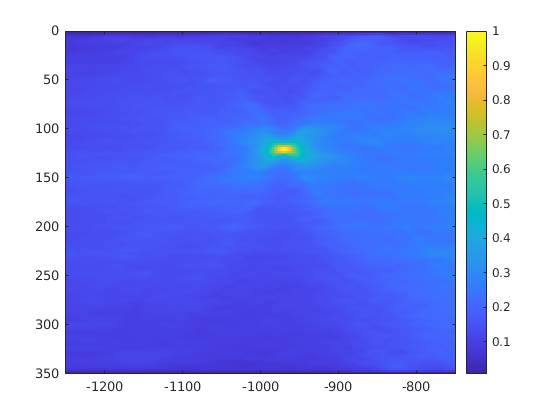

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar

save('-1200to1200.mat')


[maxValue, maxInd] = max(energy_values, [], "all", "linear")

maxValue = 5.8069e-04

maxInd = 24561

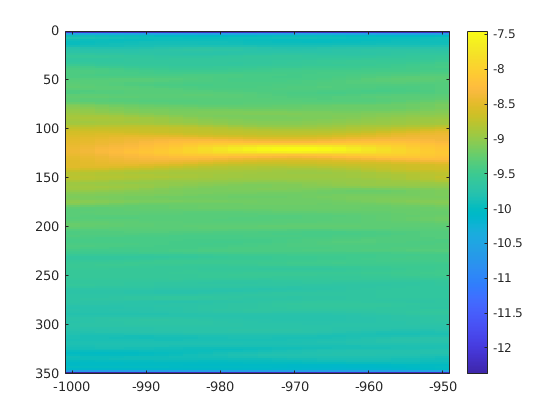

image(all_x_coor, all_y_coor,log(energy_values), 'CDataMapping','scaled')
colorbar

dummy_en = []
for i = [-500:70:-100]
sig = get_signal_at_a_point(RecSig,i, 150);
plot(t,sig)
pause(0.5)
dummy_en(end+1)=max(max(sig));
end

sig = get_signal_at_a_point(RecSig,-1000, 150);
plot(t,sig)

image(all_x_coor, all_y_coor,energy_values/(max(max(energy_values))), 'CDataMapping','scaled')
colorbar


% plot(green(0, 1*25, 1500, 150, flip(RecSig(1,:)),t))

function all_sig = get_signal_at_a_point(RecSig, destination_x, destination_y)
dt = 2e-4;
% t = -6.4+dt:dt:6.4;
t = dt:dt:6.4;
all_sig = 0;
for i = 1:9
    recv_signal = RecSig(i,:)';
%     disp('rcv signal')
%     plot(recv_signal)
    padding = zeros(size(t,2)-size(recv_signal,1),1);
    padded_recv_signal = cat(1,padding,recv_signal);
    
%     disp('padded rcv signal')
%     figure()
%     plot(padded_recv_signal)
%     
    reversed_padded_recv_signal = flip(padded_recv_signal);
%     disp('reveresed padded rcv signal')
%     figure()    
%     plot(t,reversed_padded_recv_signal)
    
    sig = green(0, i*25, destination_x, destination_y, reversed_padded_recv_signal,t);
    if all_sig==0
        all_sig = sig;
    else
        all_sig = all_sig+sig;
        %plot(all_sig)
        %pause(0.5)
    end
%     disp('reconstructed_signal')
%     figure()
%     plot(sig)
    
%     
end
%%%%%%

end


function R = green(xs, zs, x, z,signal, t)
h = 350; %max_height
xs = xs;
zs = zs;
x = x;
z = z;
c = 1500;

dt = 2e-4;
fs = 1/dt;

%fs = 1.0e4;

r0 = sqrt((x-xs)^2 + (z-zs)^2);
this_signal = delayseq(signal,r0/c,fs);
R = this_signal/(4*pi*r0);

for j = -8:8
    if j ==0
        continue
    end
    if rem(j,2)==0
       r = sqrt((x-xs)^2 + (z-zs+j*h)^2);
       eps = 1;
    else
       r = sqrt((x-xs)^2 + (z+zs-(j+1)*h)^2);
       eps = -1;
    end
    this_signal = delayseq(signal,r/c,fs);
    R = R+(eps/(4*pi*r) *this_signal);
end

end



